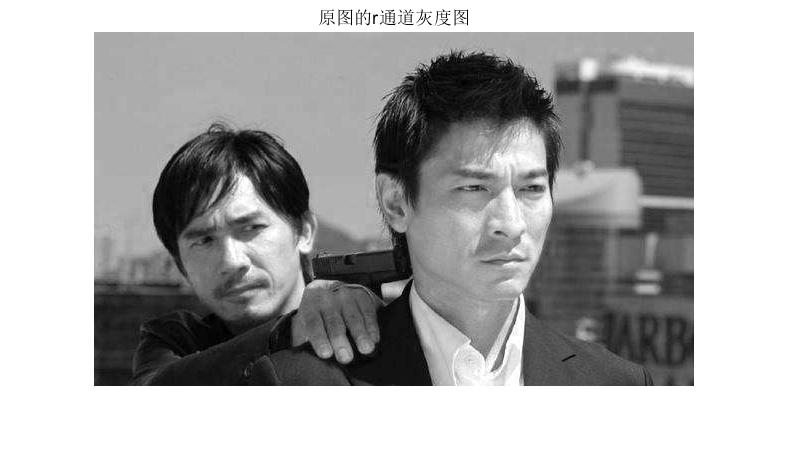

image=imread('06-刘德华.jpg');


%提取r通道数据
gray_r=image(:,:,1);
figure;
imshow(gray_r);%展示r通道数据
title('原图的r通道灰度图');

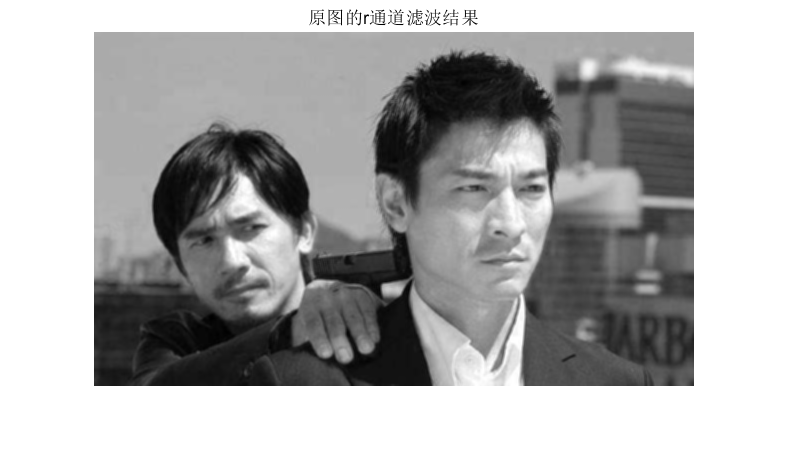

gray_out=MeanFilter(gray_r);
figure;
imshow(gray_out);%展示均值滤波结果
title('原图的r通道滤波结果');

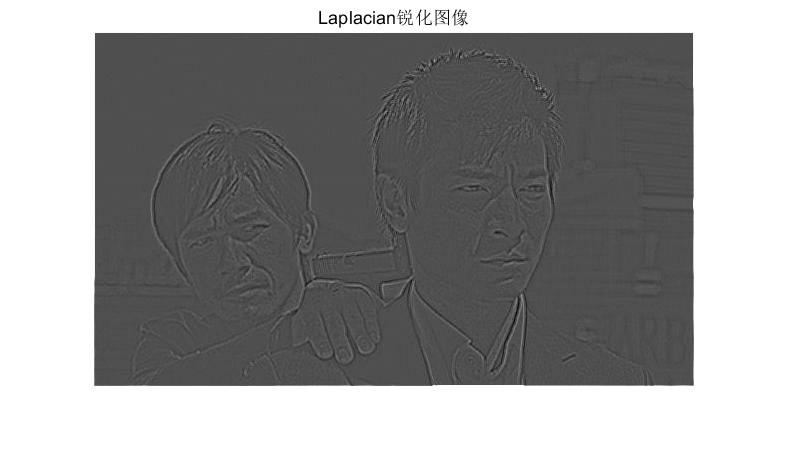


im = double(gray_out);
%定义卷积核
H1 = [0 -1 0;
     -1 4 -1;
      0 -1 0];
im_filter1 = filter2(H1,im);%使用卷积核进行滤波


minV = min(min(im_filter1));

delta = 0;
if(minV<0)
    delta = abs(minV);
end
im1 = im_filter1 + delta;
figure;
imshow(uint8(im1));
title('Laplacian锐化图像');

function [ filtered ] = MeanFilter( noise )%实现均值滤波器

    filtered = noise;

    h = size(filtered, 1);
    w = size(filtered, 2);

    for i = 1 : h
        for j = 1 : w
            %对边界条件进行简单处理
            up = max(i - 1, 1);
            down = min(i + 1, h);
            left = max(j - 1, 1);
            right = min(j + 1, w);
            filtered(i, j) = mean(mean(noise(up : down, left : right)));
        end
    end

end


